## Example of Dynamic System Stability

In this example we're going to be looking at a single input single outpu (SISO) plant system with a simple gain controller.

## Plant Model

Our plant model is defined by the following transfer function

Plant = tf([1 2.6],[2 2.4 1.6 0])

Plant =
 
          s + 2.6
  -----------------------
  2 s^3 + 2.4 s^2 + 1.6 s
 
Continuous-time transfer function.



We can close the feedback loop with the following code.  The first argument is our plant model, and the second argument is the feedback model, which in our case is a direct connection. This is represented as a multiplication of the output signal by 1.

T = feedback(Plant, 1)

T =
 
             s + 2.6
  -----------------------------
  2 s^3 + 2.4 s^2 + 2.6 s + 2.6
 
Continuous-time transfer function.



## Poles of the System

The Poles of the closed-loop transfer function determine the closed-loop stability.

pole(T)

ans =   -1.0961 + 0.0000i
  -0.0520 + 1.0878i
  -0.0520 - 1.0878i


The complex poles of this system all have real components that are negative.  This means that our closed-loop system is stable.  

## Root-Locus

The Root-Locus plot shows how the poles and zeros change in response to a change in feedback gain.  

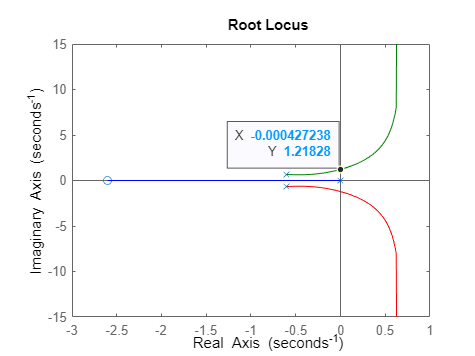

rlocus(Plant)

We can see that a 20% gain in loop feedback results in an unstable sytem. This isn't very myuch